[filename, pathname] = uigetfile({'*.xls;*.xlsx', 'Excel Files (*.xls, *.xlsx)'; ...
                                  '*.*', 'All Files (*.*)'}, ...
                                  'Select an Excel file');
fullpath = fullfile(pathname, filename);
data_read= readtable(fullpath, 'Range', 'A:B'); 
dataMatrix_FEA = table2array(data_read);

[filename, pathname] = uigetfile({'*.xls;*.xlsx', 'Excel Files (*.xls, *.xlsx)'; ...
                                  '*.*', 'All Files (*.*)'}, ...
                                  'Select an Excel file');
fullpath = fullfile(pathname, filename);
data_read= readtable(fullpath, 'Range', 'A:B'); 
dataMatrix_EXP = table2array(data_read);

% 
% % Load your data, here it's assumed to be in a two-column matrix called 'data'
 data = xlsread('phaseAcurrent.xlsx'); % Uncomment this line to load your data

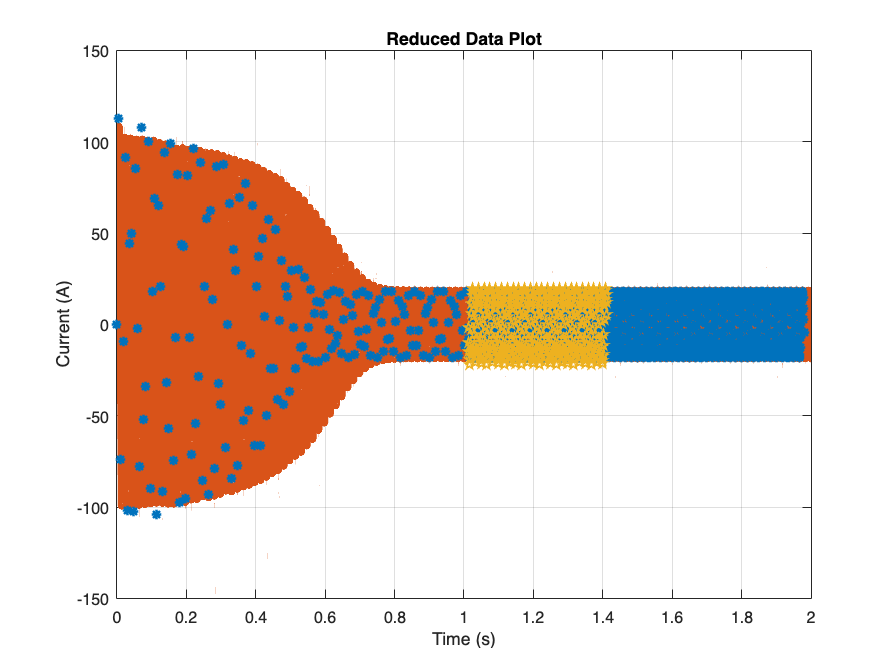

% % For this example, let's create some sample data
% data = [(0:0.01:0.1)', (0:1:10)'];

% Define the new step size, for example, every 5th data point
step_size = 30;
step_size_2 = 5;
% Select data points with the new step size
reduced_data = data(1:step_size:5062, :);

reduced_data_2 = data(5063:step_size_2:end, :);
% Concatenate the two parts
reduced_data_con = [reduced_data; reduced_data_2];


blue = [0 0.4470 0.7410];
red = [0.8500 0.3250 0.0980];
Y = [0.9290 0.6940 0.1250];
% Plot the reduced data

plot(dataMatrix_FEA(1:100000,1),dataMatrix_FEA(1:100000,2),'Color', red, 'LineWidth', 5);
hold on;
plot(reduced_data_con(:,1), reduced_data_con(:,2), '*','Color', blue, 'LineWidth', 1.5); % 'o-' means circle markers with line

step_size = 2500;

% Select data points with the new step size
reduced_data_EXP = dataMatrix_EXP(1:step_size:end, :);


plot(reduced_data_EXP(:,1),reduced_data_EXP(:,2),'pentagram','Color', Y, 'LineWidth', 1);
xlabel('Time (s)');
ylabel('Current (A)');
title('Reduced Data Plot');
grid on;
hold off;


% Optionally, you can save the plot as an image
% saveas(gcf, 'reduced_data_plot.png');
